# Robótica taller 1

*Daniel Esteban Ramirez Chiquillo*

*dramirezch@unal.edu.co*

*c.c. 1002479235*

## 1

Tenemos dos vectores libres A y B expresados en un marco de referencia M1.

A = [a1, a2, a3]

B = [b1, b2, b3]

La representación de estos vectores en un marco de referencia M2 está dada por:

A' = Tm A = [a1', a2', a3']

B' = Tm B = [b1', b2', b3']

En donde Tm es una matriz de transformación.

Calculamos el producto punto de A' y B':

A' dot B' = (Tm A)^T (Tm B)

A' dot B' = Tm^T A^T Tm B

Como Tm^T Tm = I para cualquier matriz de transformación Tm:

A' dot B' = A^T B

Recordamos la definición del producto punto de A y B:

A dot B = A^T B

Con esto queda demostrado que:

A dot B = A' dot B'

Por lo que el producto punto de dos vectores libres no depende del los marcos de referencia seleccionados.

## 2

**¿Qué es una base?**

Una base es un conjunto de vectores linealmente independientes que pueden representar todos los vectores de un espacio vectorial específico mediante una combinación lineal.

**¿Qué es un sistema de coordenadas?**

Un sistema de coordenadas es un sistema que utiliza uno o más números, o coordenadas, para determinar la posición única de los puntos u otros elementos geométricos en un espacio euclidiano.

## 3

**a)**

w = [0, -4]';
S = [[1, -3]', [2, -2]'];
x = S \ w

x =     2.0000
   -1.0000


**b)**

W = [6 -5; 1 -2];
S = [[1 -1; 1 0],[-1 1; 0 1],[1 0; -1 1]];
X = S \ W

X =     3.5000   -3.5000
         0         0
         0         0
         0         0
    2.5000   -1.5000
         0         0


## 4

i = [1 0 0]';
j = [0 1 0]';
k = [0 0 1]';
base_canonica = [i,j,k]

base_canonica =      1     0     0
     0     1     0
     0     0     1


Para obtener la combinación lineal se realiza el mismo procedimiento que en el ejercicio anterior.


d = [4 2 -1]';
clvbc = base_canonica \ d

clvbc =      4
     2
    -1


Las proyeciones del vector en la base son los productos punto del vector con los vectores de la base. (Multiplicado por el vector de la base para darle dirección.)

proy_i = dot(d, i) * i

proy_i =      4
     0
     0


proy_j = dot(d, j) * j

proy_j =      0
     2
     0


proy_k = dot(d, k) * k

proy_k =      0
     0
    -1


Teniendo en cuenta la formula:

A dot B = |A| |B| cos(theta)

cos(theta) =  |A| |B| / (A dot B)

cos_i = norm(proy_i) / (norm(i)*norm(d))

cos_i = 0.8729

cos_j = norm(proy_j) / (norm(j)*norm(d))

cos_j = 0.4364

cos_k = norm(proy_k) / (norm(k)*norm(d))

cos_k = 0.2182

Gráfica:

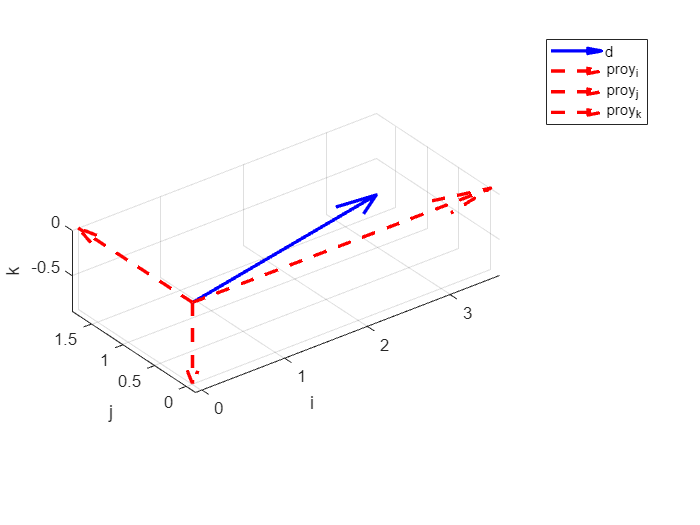

% quiver3 plotea un vector 3D de un punto x,y,z a otro x2,y2,z2
% se grafica el vector d
quiver3(0, 0, 0, d(1), d(2), d(3), 'b', 'LineWidth', 2, 'MaxHeadSize', 0.5);
hold on;
% se grafican las proyecciones
quiver3(0, 0, 0, proy_i(1), proy_i(2), proy_i(3), 'r--', 'LineWidth', 2, 'MaxHeadSize', 0.5);
quiver3(0, 0, 0, proy_j(1), proy_j(2), proy_j(3), 'r--', 'LineWidth', 2, 'MaxHeadSize', 0.5);
quiver3(0, 0, 0, proy_k(1), proy_k(2), proy_k(3), 'r--', 'LineWidth', 2, 'MaxHeadSize', 0.5);

% límites y tamaños de los ejes
xlim([-5, 5]);
ylim([-5, 5]);
zlim([-5, 5]);
axis equal;

% labels para los ejes
xlabel('i');
ylabel('j');
zlabel('k');

% leyenda
legend('d', 'proy_i', 'proy_j', 'proy_k');

## 5

A = [-5 2 10; -3 1 -6; 1 -3 3];
B = [-2 2; 3 -1; -3 2];
C = [1 0 -1; 0 1 1];
D = [-15 24 -2; 3 -5 0; 8 -13 1];

(Se asume que se pide realizar multiplicación de matrices y no producto punto como dice el enunciado.)

**a)**

ans_5a = (A * B)'

ans_5a =    -14    27   -20
     8   -19    11


**b)**

ans_5b = D' * A'

ans_5b =    161     0     0
  -260     1     0
    20     0     1


**c)**

No se puede realizar: (B' * B)^-1) da como resultado una matriz 2x2 y esta no se puede multiplicar con una matriz 3x2.

bb = (B' * B)^-1

bb =     0.3103    0.4483
    0.4483    0.7586


bt = B'

bt =     -2     3    -3
     2    -1     2


**d)**

No se puede realizar: B*C es una matriz 3x3 y C*B es 2x2. Estas dos no se pueden restar

bc = (B * C)

bc =     -2     2     4
     3    -1    -4
    -3     2     5


cb = (C * B)

cb =      1     0
     0     1


**e)**

(Es la misma que la anterior.)

**f)**

ans_5f = (B' * (2*B)) * (C * B)

ans_5f =     44   -26
   -26    18


## 6

### a)

R1 = [0.4330 -0.75 -0.5; 0.4356 0.6597 -0.6124; 0.7891 0.0474 0.6124];

#### Ortogonal

Si la matriz es ortogonal, la multiplicación de ella misma con su transpuesta debe dar como resultado la matriz identidad.

R1*R1'

ans =     1.0000    0.0000   -0.0001
    0.0000    1.0000   -0.0000
   -0.0001   -0.0000    1.0000


Por lo tanto, la matriz es **ortogonal**. (Los decimales que aparecen en la diagonal secundaria son errores de aproximación de Matlab.)

#### Determinante igual a 1

det(R1)

ans = 1.0000

Esto comprueba otra propiedad, que su **determinante es igual a 1**.

#### Transpuesta e inversa

R1'

ans =     0.4330    0.4356    0.7891
   -0.7500    0.6597    0.0474
   -0.5000   -0.6124    0.6124


R1^-1

ans =     0.4330    0.4356    0.7892
   -0.7500    0.6597    0.0474
   -0.4999   -0.6124    0.6124


Se puede ver que las dos matrices son iguales, por lo tanto, l**a transpuesta y la inversa de la matriz son iguales**.

### b)

Las imprecisiones en los cálculos pueden hacer que el determinante se calcule como 0 cuando no debería ser así, llevando a la conclusión de que la matriz es singular y no tiene inversa. Del mismo modo, las imprecisiones en el cálculo de la matriz inversa pueden conducir a resultados incorrectos al resolver sistemas lineales de ecuaciones.

El comando que genera la cantidad más pequeña con la que Matlab puede trabajar es:

eps

ans = 2.2204e-16

## 7

R_B_A = [1 0 0; 0 (sqrt(3)/2) -1/2; 0 1/2 (sqrt(3)/2)];
R_C_A = [0 0 -1; 0 1 0; 1 0 0];

Para obtener la tercera matriz de rotación se hace la siguiente operación:

R_C_B = R_B_A' * R_C_A

R_C_B =          0         0   -1.0000
    0.5000    0.8660         0
    0.8660   -0.5000         0


R_C^B se obtiene de esta manera porque si partimos de un vector en B:

- Multiplicamos por R_B^A', pasaremos de B a A.

- Multiplicamos (con el vector ahora en A) por R_C^A, pasaremos de A a C.